clc
clear
close all
set(0, 'DefaultLineLineWidth', 2);
set(0, 'defaultAxesFontSize', 12)
set(0, 'defaultAxesTickLabelInterpreter','latex');
set(0, 'defaultlegendInterpreter','latex')

## The system 

We will consider a LTI system of the form:


$$\begin{cases} \underset{n \text{ x } 1}{x_{t+1}} = \underset{ n \text{ x } n}{A} \cdot \underset{n \text{ x } 1}{x_t} + \underset{n \text{ x } m}{B} \cdot  \underset{m \text{ x } 1}{u_t} + \underset{n \text{ x } l}{K} \cdot \underset{l \text { x } 1}{e_t} \quad \quad (1)\\ \underset{l \text{ x } 1}{y_t} = \underset{l \text{ x } n}{C} \cdot  \underset{n \text{ x } 1}{x_t} + \underset{l \text{ x } m}{D} \cdot \underset{m \text{ x } 1}{u_t} + \underset{l \text{ x } 1}{e_t} \quad \quad \quad \ (2) \end{cases}$$


where 

- the inputs $u_t \in \mathbb{R}^m  \ \Leftrightarrow \ m =$ number of inputs, 

- the outputs $y_t \in \mathbb{R}^l \ \Leftrightarrow \ l =$ number of outputs,

- the states $x_t \in \mathbb{R}^n \ \Leftrightarrow n =$ number of states.

- the noise sequence $e_t$ is supposed to be $\sim WN(0; \Sigma_e)$ with $\Sigma_e = \mathbb{E}[e_k e_k^T]$ and $\Sigma_{ij} = \mathbb{E}[e_i e _k^T]=0 \text{ for } i \ne k$

- $N_s =$ number of samples

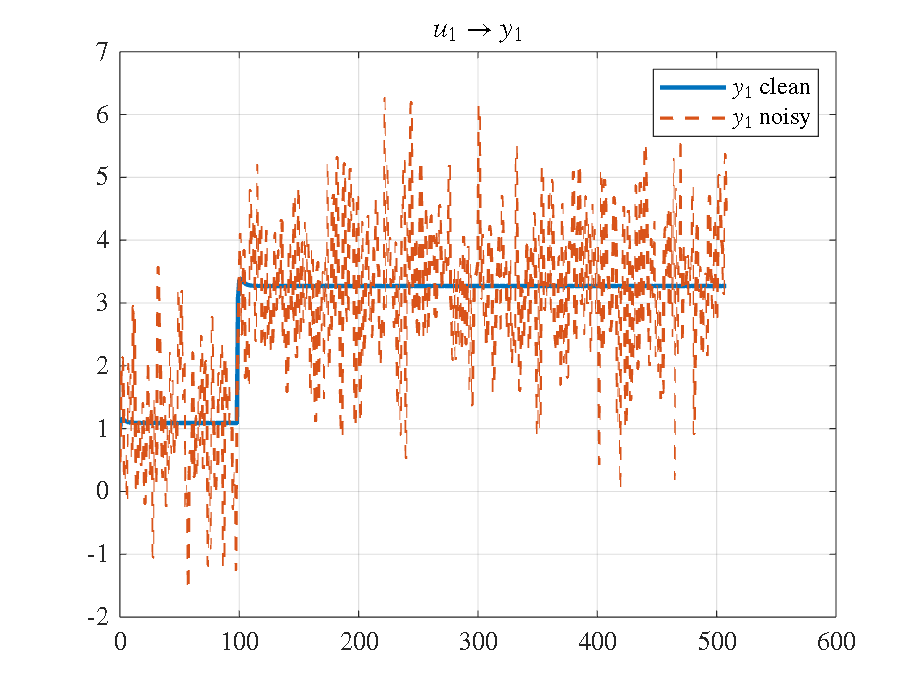

tol = 1e-10;                                % used to check null value
m = 3;
l = 2;
n = 2; 
Ns = 509;
Ts = 1;                                     % sampling time
t = (0:Ns-1) * Ts;                          % time of sampling
A = [0.7  0; 0  0.3];                       % states matrix [n x n]
B = [-0.1  0.2  0.6; 0.9 -0.5 -0.4];        % inputs matrix [n x m]
C = [0.5  0.2; 0.6 -0.8];                   % outputs matrix [l x n]
D = [1 0 0; 0 0 0];                         % [l x m]
K = [1 0; 0 1; 0 0];                        % [n x l] 

rng(42);
e = randn(Ns, l);
x = zeros (Ns, n);
y = zeros (Ns, l);
u = zeros(Ns,m);
u(1:99,1)=1; u(100:Ns,1)=3; 
u(1:149,2)=1; u(150:Ns,1)=3; 
u(1:199,3)=1; u(200:Ns,1)=3; 

y_clean = zeros(Ns, l, m);
sys = cell(m,1); 
for j = 1:m
    U = u(:,j);                                 % input Matrix
    sys{j} = ss(A, B(:,j), C, D(:,j), 1);       % system state space model
    y_clean(:,:,j) = lsim(sys{j}, U, t);        % deterministic output for each input
end
y_noisy = y_clean + e;                          % stochastic output for each input
y = sum(y_clean, 3);                            % deterministic output as sum of all inputs

% Grafico y_1
figure;
plot(t, y_clean(:,1,1), 'LineWidth', 2); hold on;
plot(t, y_noisy(:,1,1), '--', 'LineWidth', 1.5);
grid on;
legend('$y_1$ clean','$y_1$ noisy','Interpreter', 'latex');
title('$u_1 \to y_1$','Interpreter', 'latex');

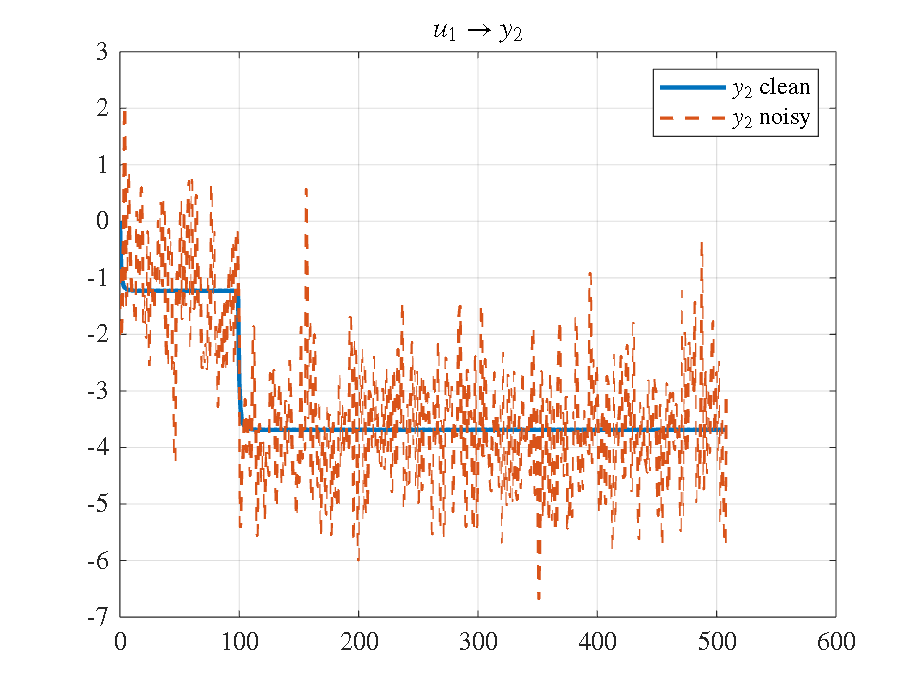


% Grafico y_2
figure;
plot(t, y_clean(:,2,1), 'LineWidth', 2); hold on;
plot(t, y_noisy(:,2,1), '--', 'LineWidth', 1.5);
grid on;
legend('$y_2$ clean','$y_2$ noisy','Interpreter', 'latex');
title('$u_1 \to y_2$','Interpreter', 'latex');

## Matrix input-output equations


$$\underset{lN \text{ x } j}{Y_f} = \underset{lN \text{ x } n}{\Gamma_N} \cdot\underset{n \text{ x } j}{X_f} + \underset{lN \text{ x } mN}{H_N} \cdot \underset{mN \text{ x } j}{U_f} + \underset{lN \text{ x } lN}{H_N^S} \cdot \underset{lN \text{ x } j}{E_f} \quad \quad (3)$$



$$\underset{lM \text{ x } j}{Y_p} = \underset{lM \text{ x } n}{\Gamma_M} \cdot  \underset{n \text{ x } j}{X_p} + \underset{lM \text{ x } mM}{H_M} \cdot \underset{mM \text{ x } j}{U_p} + \underset{lM \text{ x } lM}{H_M^S} \cdot \underset{lM \text{ x } j}{E_p} \quad \quad (4)$$



$$\underset{mM \text{ x } j}{U_p} = \left( \begin{array}{c} u_1 & u_2 & ... & u_j \\ u_2 & u_3 & ... & u_{j+1} \\ ... & ... & ... & ... \\ u_M & u_{M+1} & ... & u_{j+M-1} \end{array} \right) \quad \quad (5)$$



$$\underset{mN \text{ x } j}{U_f} = \left( \begin{array}{c} u_{M+1} & u_{M+2} & ... & u_{M+j} \\ u_{M+2} & u_{M+3} & ... & u_{M+j+1} \\ ... & ... & ... & ... \\ u_{M+N} & u_{M+N+1} & ... & u_{M+N+j} \end{array} \right) \quad \quad (6)$$


In a similar way, we define the block Hankel matrices $\underset{lM \text{ x } j}{Y_p}, \quad \underset{lN \text{ x }j}{Y_f}, \quad  \underset{lM \text{ x } j}{E_p}, \quad \underset{lN \text{ x }j}{E_f,} $

$j$ must be much larger (tipically 100 times) than $N,M$: $j \ge 100 \cdot \max(N,M)$ but $N_s = M+N+j$


$$\underset{(l+m)M \text{ x } j}{W_p} \triangleq \left( \begin{array}{c} Y_p \\ U_p \end{array} \right)$$


The past and the future state sequences are definited as


$$\underset{n \text{ x } j}{X_p} = (x_1 \quad x_2 \quad ... \quad x_j)$$



$$\underset{n \text{ x } j}{X_f} = (x_{M+1} \quad x_{M+2} \quad ... \quad x_{M+j})$$


$\underset{lq \text{ x } n}{\Gamma_q} = \left( \begin{array}{c} C \\ CA \\ ... \\ C A^{q-1} \end{array} \right)$ , $\quad \underset{lq \text{ x } mq}{H_q}= \left( \begin{array}{c} D & 0 & ... & 0 \\ CB & D & ... & 0 \\ ... & ... & ... & ... \\ C A^{q-2}B & CA^{q-3} B & ... & D \end{array} \right)$, $\quad \underset{lq \text{ x } lq}{H_q^S}= \left( \begin{array}{c} I_l & 0 & ... & 0 \\ CK & I_l & ... & 0 \\ ... & ... & ... & ... \\ C A^{q-2}K & CA^{q-3} K & ... & I_l \end{array} \right)$ 

where $q \in \mathbb{N}_0$, $\Gamma_q$ is the extended observability matrix, $H_q$ and $H_q^S$ are the Toeplitz matrices containing the impulse response of the system to the deterministic input $u_k$ and to the stochastic input $e_k$ respectively.

M = 4;
N = 5;
j = 500;

Up = zeros(m*M, j);
Uf = zeros(m*N, j);
Yp = zeros(l*M, j);
Yf = zeros(l*N, j);
for i = 1:j
    idp = i : i + M - 1;                    % index for past Hankel Matrices
    idf = M + i : M + i + N - 1;            % index for future Hankel Matrices
    Up(:,i) = reshape(u(idp,:)', m*M, 1);   % [mM x j] = [12 x 500]
    Yp(:,i) = reshape(y(idp,:)', l*M, 1);   % [mN x j] = [15 x 500]
    Uf(:,i) = reshape(u(idf,:)', m*N, 1);   % [lM x j] = [ 8 x 500]
    Yf(:,i) = reshape(y(idf,:)', l*N, 1);   % [lN x j] = [12 x 500]
end

## First step of subspace identification problem

Using the QR decomposition:


$$\left( \begin{array}{c} \underset{(l+m)M \text{ x } j}{W_p} \\ \underset{mN \text{ x } j}{U_f} \\ \underset{lN \text{ x } j}{Y_f} \end{array} \right) = \left( \begin{array}{c} \underset{(l+m)M \text{ x } (l+m)M}{R_{11}} & 0 & 0 \\ \underset{mN \text{ x } (l+m)M}{R_{21}} & \underset{mN \text{ x } mN}{R_{22}} & 0 \\ \underset{lN \text{ x } (l+m)M}{R_{31}} & \underset{lN \text{ x }mN}{R_{32}} & \underset{lN \text{ x } lN}{R_{33}} \end{array} \right) \cdot \left( \begin{array}{c} Q_1^T \\ Q_2^T \\ Q_3^T \end{array} \right) \quad \quad (9)$$


by posing:


$$\underset{lN \text{ x } ((l+m)M+mN)}{L} = (R_{31}  \ R_{32}) \cdot \left( \begin{array}{c}{R_{11} & 0 \\ R_{21} & R_{22} \end{array} \right)^{\dagger}$$


We know that:


$$\underset{lN \text{ x } (l+m)M}{L_w} = L(:,1:M(m+l))$$



$$\underset{lN \text{ x } mN}{L_u} = L(:,M(m+l) + 1: end)$$


It appears that there is a minor inconsistency in the original segmentation of the matrix $L$. After careful examination, we found that adjusting the dimensions to correspond to the past window length $M$ ensures consistency with the theoretical derivation and numerical implementation.

Wp = [Yp; Up];                              % [(l+m)M x j] = [20 x 500]
Z  = [Wp; Uf; Yf];                          % [(l+m)(M+N) x j] = [45 x 500]

[Q_tmp, R_tmp] = qr(Z');                    % Z' = Q_tmp * R_tmp
R = R_tmp';                                 % R inferior triangular matrix
Q = Q_tmp';                                 % Q ortogonal matrix

if norm(triu(R,1), 'fro') < tol
    fprintf('R is triangular: OK \n');
else
    fprintf ('R is not triangular: NOK\n');
end

R is triangular: OK 


if norm(Q'*Q - eye(size(Q)), 'fro') < tol
    fprintf('Q is ortogonal: OK \n');
else
    fprintf('Q is not ortogonal: NOK\n');
end

Q is ortogonal: OK 



nw = (l+m)*M;                               % Wp row number = 20
nu = m*N;                                   % Uf row number = 15
ny = l*N;                                   % Yf row number = 10
R11 = R(1:nw, 1:nw);                        % [20 x 20]
R12 = zeros(nw, nu);                        % [20 x 15]
R21 = R(nw+1:nw+nu, 1:nw);                  % [15 x 20]
R22 = R(nw+1:nw+nu, nw+1:nw+nu);            % [15 x 15]
R31 = R(nw+nu+1:end, 1:nw);                 % [10 x 20]
R32 = R(nw+nu+1:end, nw+1:nw+nu);           % [10 x 15]
R33 = R(nw+nu+1:end, nw+nu+1:nw+nu+ny);     % [10 x 10]

L = [R31 R32] * pinv([R11 R12; R21 R22]);   % [10 x 35]
Lw = L(:,1:M*(m+l));                        % [10 x 20] diverso dal paper
Lu = L(:,M*(m+l)+1:end);                    % [10 x 15]

## Second step of subspace identification problem

In this step we'll calculate the SVD of $L_w$.


$$\underset{lN \text{ x } M(m+l)}{L_w} = \left(U_1 \ U_2\right) \cdot \left( \begin{array}{c} S_1 & 0 \\ 0 & S_2 \end{array} \right) \cdot \left( \begin{array}{c} V_1^T \\ V_2^T \end{array}\right) \approx U_1 \ S_1 \ V_1^T \quad \quad (10)$$$
 

where the rank $\hat n$ is determinated by inspecting the number of dominant singular value of $S_1$, This is an approximation of the order $n$ of the system. Important i sthat, under the assumption that the number of columns in the data block Hankel matrices $Y_f, U_f, W_p$ is infinite $( j = \infty)$ there exists a direct link between $L_W$ and the observability matrix $\Gamma_N$ and the state sequence $X_f$.


$$\underset{lN \text{ x } \hat n}{\Gamma_N} =  \underset{lN \text{ x } \hat n}{U_1} \cdot  \underset{\hat n \text{ x } \hat n}{S_1^{1/2}}$$



$$ \underset{\hat n \text{ x } j}{\hat X_f} = \underset{\hat n \text{ x } \hat n}{S_1^{1/2}} \cdot  \underset{\hat n \text{ x } M(m+l)}{V_1^T} \cdot  \underset{M(m+l) \text{ x } j}{W_p}$$


It (Van Overschee and De Moor 1996) it is proven that $\hat X_f$ is a Kalman filter estimate or the state sequence $X_f$

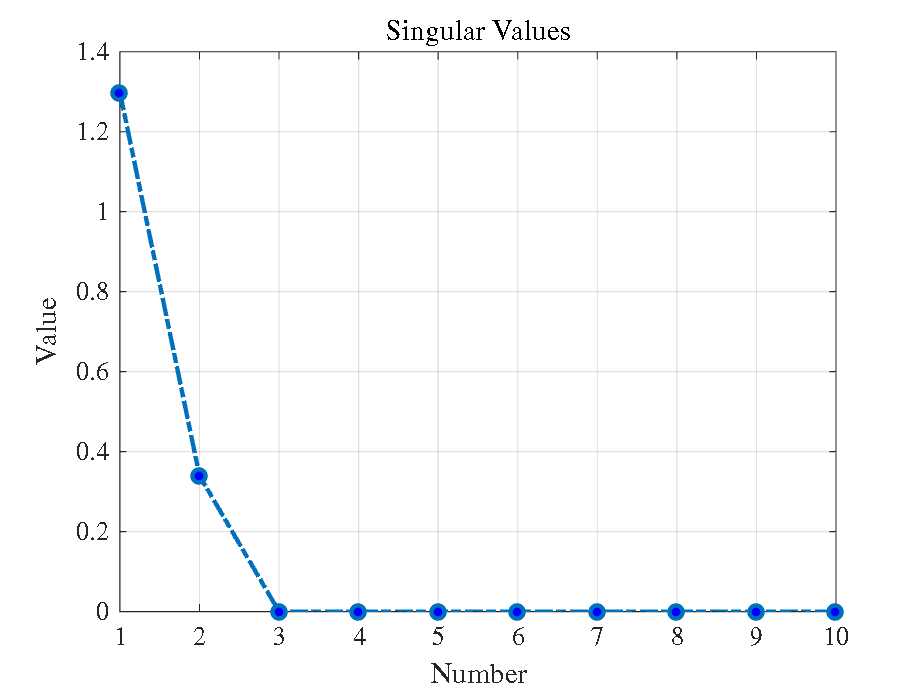

singvals = svd(Lw);
figure;
nsv = length(singvals);
plot(1:nsv, singvals, '-.o', 'MarkerFaceColor','b', 'MarkerSize',6);
grid on;
xlabel('Number','Interpreter','latex');
ylabel('Value','Interpreter','latex');
title('Singular Values','Interpreter','latex');
xlim([1 nsv]);
xticks(1:1:nsv);

hat_n = sum(singvals > tol * max(singvals))

hat_n = 2

[U_,S_,V_] = svd(Lw);
U1 = U_(:, 1:hat_n);                % [10 x 3]
S1 = S_(1:hat_n, 1:hat_n);          % [3 x 3]
V1 = V_(:, 1:hat_n);                % [20 x 3]
Gamma_N = U1 * sqrt(S1);            % [10 x 3]
hat_Xf = sqrt(S1) * V1' * Wp;       % [3 x 500]

## Subspace Identification based Implementation of MPC

Solve the following least square problem for the unknown parameters $L_w$ and $L_u$


$$\underset{L_w, \ L_u}{\min} \left|\left| Y_f - (L_w \ L_u) \cdot \left( \begin{array}{c} W_p \\ U_f \end{array} \right) \right|\right|^2_F = \underset{L_w, \ L_u}{\min} \left|\left| Y_f - L_w \cdot Wp - L_u \cdot U_f   \right|\right|^2_F$$


This is a linear least squares having as closed solution:


$$\underset{ lN \text{ x } (M(l+m)+mN)}{L} = [ \underset{lN \text{ x } M(m+l)}{L_w} \ \underset{lN \text{ x } mN}{L_u} ] = \underset{lN \text{ x } j}{Y_f} \cdot \underset{j \text{ x } (M(l+m)+mN)}{ \left[ \begin{array}{c} W_p \\ U_f \end{array} \right]^\dagger}$$


L_ls = Yf * pinv([Wp; Uf]);
Lw_ls = L_ls(:,1:M*(m+l));                        % [10 x 20] 
Lu_ls = L_ls(:,M*(m+l)+1:end);                    % [10 x 15]
err_w = norm(Lw - Lw_ls, 'fro') / norm(Lw, 'fro');
err_u = norm(Lu - Lu_ls, 'fro') / norm(Lu, 'fro');

if err_w < tol
    fprintf('QR+SVD and closed-form LS yield the same Lw matrix up to numerical accuracy: OK\n');
else
    fprintf('The Lw matrix obtained via QR+SVD does not coincide with the closed-form LS solution within numerical precision: NOK\n');
end

QR+SVD and closed-form LS yield the same Lw matrix up to numerical accuracy: OK



if err_u < tol
    fprintf('QR+SVD and closed-form LS yield the same Lu matrix up to numerical accuracy: OK\n');
else
    fprintf('The Lu matrix obtained via QR+SVD does not coincide with the closed-form LS solution within numerical precision: NOK\n');
end

QR+SVD and closed-form LS yield the same Lu matrix up to numerical accuracy: OK


The SPC prediction coincides exactly with the QR+SVD solution, confirming that both approaches yield the same predicted output.

## Evaluate in simulation the tracking performance

The output predicted is calculated as:


$$\hat Y_f = L_u \ Wp + L_u U_f$$


Only the first block of the predicted horizon is plotted because it represents the immediate next-step prediction. The real output is shifted by one step to align with this one-step-ahead prediction.

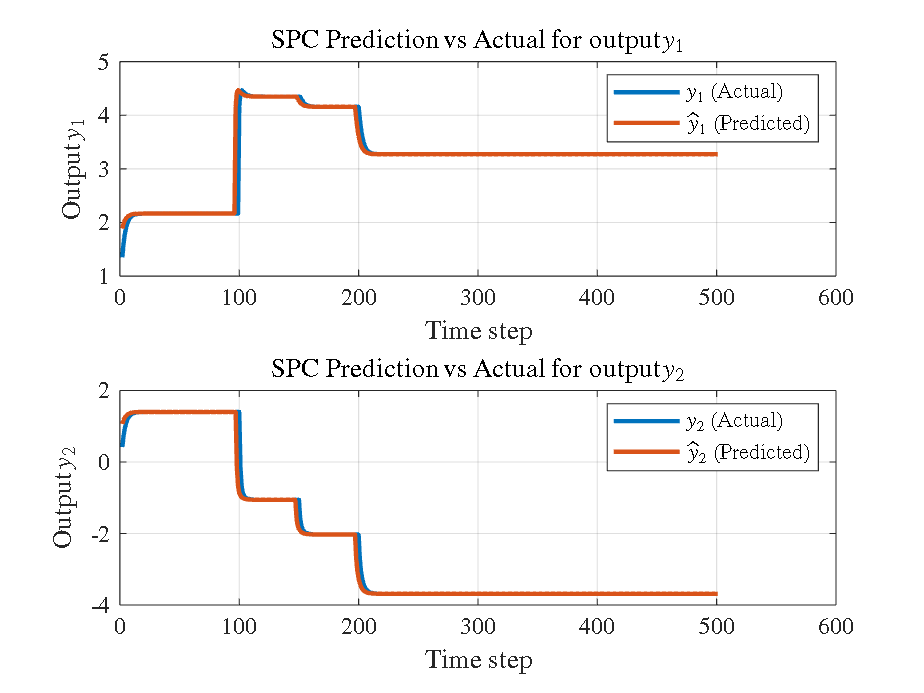

hat_Yf = Lw * Wp + Lu * Uf;
hat_y= hat_Yf(1:l, :);  % l x Ns

figure;
for i = 1:2
    subplot(2,1,i);
    % the prediction is 1 step delayed so, shift the y
    plot(2:j+1, y(2:j+1,i), 'DisplayName','$y_{' + string(i) + '}$ (Actual)');
    hold on;
    plot(2:j+1, hat_y(i,:).', 'DisplayName',['$\hat y_{' num2str(i) '}$ (Predicted)']);
    grid on;
    xlabel('Time step','Interpreter','latex');
    ylabel(['Output $y_' num2str(i) '$'],'Interpreter','latex');
    title(['SPC Prediction vs Actual for output $y_' num2str(i) '$'],'Interpreter','latex');
    legend('Interpreter','latex');
end